# Locate blinks(ground truth)

## Load data

% Downsample by a factor dsFactor
dsFactor = 1;

% read lables
ds = load('rawLable.mat').rawLable;

lables = ds.detect_blinks;

% read filtered EEG data
currentDir = dir;
currentDir(1:2) = [];
for i = 1:numel(currentDir)
    if strcmp(currentDir(i).name,'RawData')
        %disp('get RawData')
        pathToEEG = fullfile(currentDir(i).folder,currentDir(i).name);
        break
    end
end
eegFiles = dir(pathToEEG);
eegFiles(1:2) = [];
Ds = {};
DsRaw = {};
blinkLocations = {};
frontElectrodesLabels = ["Fp1", "Fp2", "Fz"]; % , "AF3", "AF4", "F7", "F8"
categroies = {'blink', 'n/a', 'muscle-artifact'};
for k = 1:31
    tokens = strsplit(ds.Row{k}, '\');
    fileName = tokens{end};
    eegTable = readtable([pathToEEG,'\',eegFiles(k).name]);
    DsRaw{k} =eegTable(:, contains(eegTable.Properties.VariableNames, frontElectrodesLabels));
    filteredSignals = passbandBlinks(DsRaw{k}, fs);
    
    filteredSignals = array2table(filteredSignals.Variables,  'VariableNames', filteredSignals.Properties.VariableNames);
%     disp(fileName);disp(ds(k,:));
    roi = ds(k,:).detect_blinks{1};
    
    Ds{k} = getmask({filteredSignals, roi});

    
    Ds{k}{2} = categorical(Ds{k}{2},categroies);
    blinkLocations{end+1} = {blinkLocate(table2array(Ds{k}{1}),Ds{k}{2}),fileName};
end

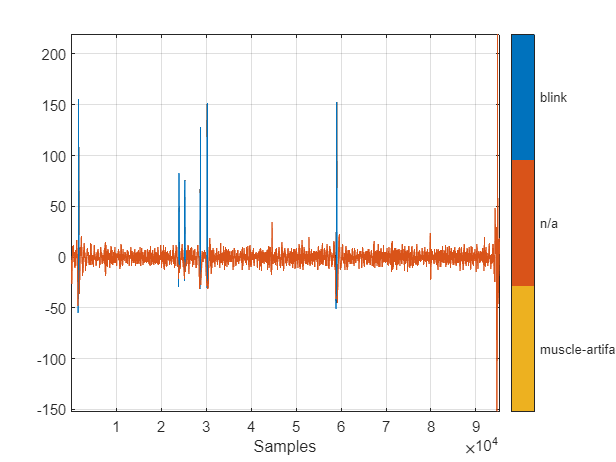

save("DataSet\blinkLocations.mat","blinkLocations","-mat");
figure;
M = signalMask(Ds{3}{2});
plotsigroi(M,Ds{3}{1}.Fp1);

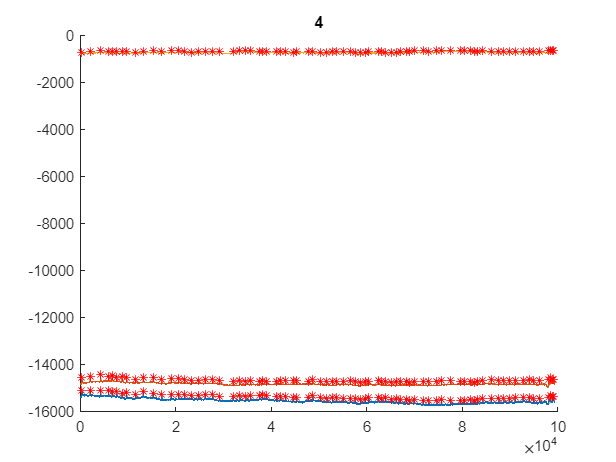

for i = 4
    signal = table2array(DsRaw{i});%table2array(Ds{i}{1});
    
    coordinate = signal(blinkLocations{i}{1},:);

    
    figure;
    
    subplot(1,1,1);
    hold on;
    plot(signal);title(i);
    plot(blinkLocations{i}{1},coordinate,'r*');
    hold off;


end

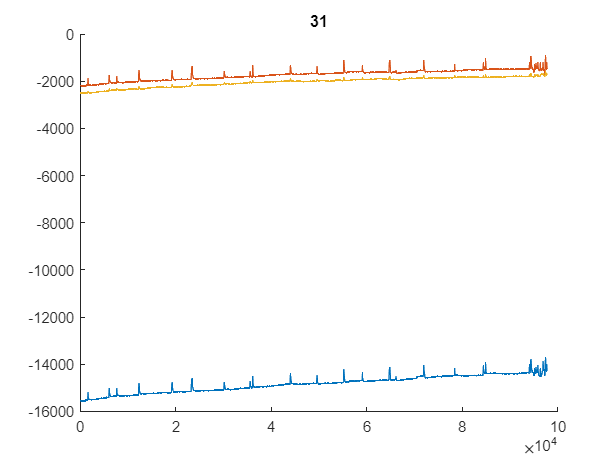

i=31;
figure;
hold on;
plot(table2array(DsRaw{i}));title(i);

plot(blinkLocations{i},coordinate,'r*')

Error using plot
Invalid data argument.

hold off;
